# A brief introduction to the dmrimatlab toolbox

# [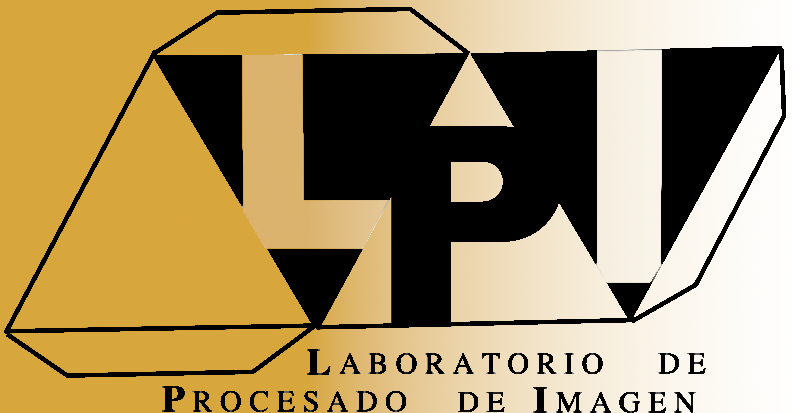](https://www.lpi.tel.uva.es/)

**dmrimatlab** is the result of a long-term effort to bring together the diffusion MRI analysis software tools that the Laboratory of Image Processing has been developing over the last decades. Of course, many of the classical methods such as DT-MRI are also integrated, so the toolbox represents a trade-off between state-of-the-art and innovative methodologies. The leitmotiv of the software is robustness and computational efficiency, so that it can be used for the systematic processing of large databases for clinical studies.

The project is hosted in [[github]](https://github.com/atriveg/dmrimatlab), and regular updates are pushed with new fucntionalities and bug fixes. Please start by downloading the code from the github repo so we can get started. The most convenient way is to directly [download the zip file](https://github.com/atriveg/dmrimatlab/archive/refs/heads/main.zip) and unzip it to a local folder.

## 1. Have you already donwloaded the code? Set-up the toolbox

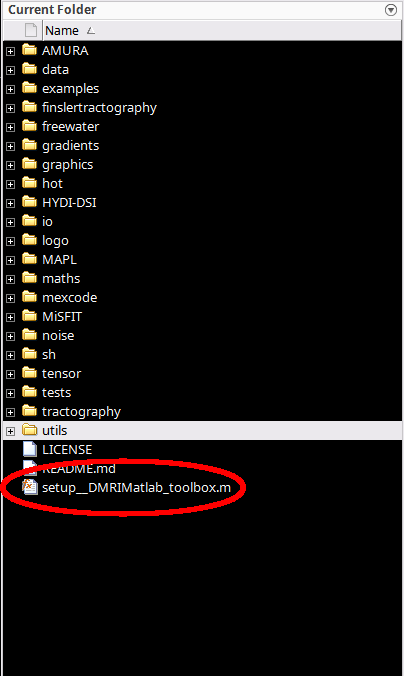

OK, first thing to do is "set up" the toolbox. From within the Matlab interface, browse to the folder that you have just unzipped. An "m" file named setup__DMRIMatlab_toolbox.m should be there. You have to run this script by either right-clicking the file and selecting Run, pressing F9 or directly typing in the command line:

The whole toolbox is command-line oriented, so that the latter is the preferred way to work. Once you run this command, you will nottice that all sub-folders become highlighted, meaning they hava been added to Matlab's path and you can use whatever command of the toolbox from wherever location in your computer.

Note this won't make any permanent change in your installation or configuration, and will only persist for your current session (meaning: you will haver to re-run the commmand each time you start Matlab).

***TO DO:***

Fix and run this code snippet to set-up the toolbox (*Ctrl+ENTER*)

currentDir = pwd; % Store the location we are at
cd('/your/location/to/the/toolbox'); % FIX THIS LINE!!!
setup__DMRIMatlab_toolbox; % Fix the proper paths for the toolbox
cd (currentDir); % Go back to your original location

## 2. Download some test data

Throughout the demo we will need some test data (diffusion MRI volumes and the meta-data required to interpret them) to illustrate the capabilities of the software. It is not directly included with the toolbox because diffusion MRI uses very large data sets that cannot fit Github's limitations. Don't worry, the toolbox itself has a download command that will connect to our servers, download the test data and put it in the proper place (if you are wondering, in a folder named "data" within the main folder of the toolbox:

***TO DO:***

Download test data from our servers. They are several hundreds of MB!!! (*Ctrl+ENTER*)

download_dmritestdata;

## 3. Compile mex binaries

As we have said, dmrimatlab pursues computational efficiency as a primary goal. If have ever used Python's dipy or MRTrix to process diffusion data, you do know that some processing tasks with diffusion MRI may become insanely heavy. Our toolbox outperforms both of them w.r.t. computational efficiently in most of these tasks (reaching one order of magnitude for some of them). How do we attain that? By combining several strategies:

- Extensive use of image masking to avoid processing undesired voxels.

- Vectorization of Matlab code, parallel for loops and "implicit expansions" (dimension broadcasting) to reduce memory requirements.

- **When vectorization is not possible, optimized C++/mex implementations have been coded: we use threads with proceesing queues that keep all processors busy all the time, and direct calls to BLAS/LAPACK libraries ensure maximum efficiency for algebraic operations.**

- **Specific optimization routines, as opposed to general purpose ones, have been coded when needed.**

The last two points imply that you will need to compile some C++ code to get things working. Don't worry: the toolbox includes an automatic script that will do this for you but, before you can run this script, we have to make sure that you have the proper developer tools:

***TO DO:***

Check if you have a working C/C++ compiler that can be used with Matlab (*Ctrl+ENTER*)

mex -setup
mex -setup C++

If the previous commands are not able to find a proper compiler, you will need to install one:

- If you're using some Linux distribution, it suffices to install the latest gcc suit from your preferred software manager. Once you're done, restarting Matlab should be enough to get things working.

- If you're using Mac OS, then XCode is your best chance. Sadly, old Intel-based MAC computers are no longer supported by our toolbox.

- If you're using Windows, even if you have Visual Studio installed, we strongly recommend to use the MinGW suite to get a gcc-like compiler installed in your system. Indeed, we test and maintain the Windows versions only for these compilers. Good news is that you can install MinGW directly from your Matlab main window, through the "Add-Ons" tool. Simply click on "Get Add-Ons" to open the Add-on explorer. In the search field, look for "MinGW" and choose the very first coincidence if finds. In the page it will open later on, simply click "Install" to get MinGW. It will take a little while and your will have to restart Matlab right after.

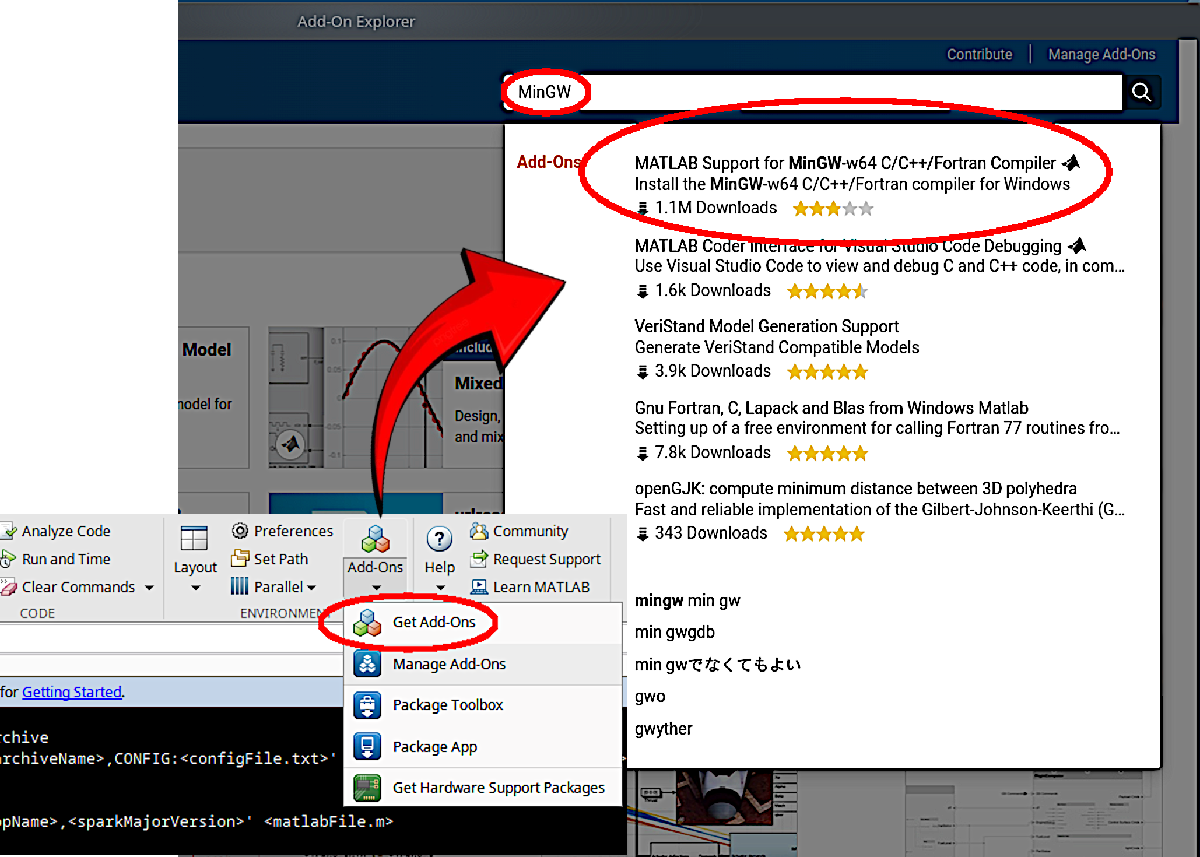

So now you have a C/C++ compiler and you're ready to compile the software.

***TO DO:***

Compile the software. It may take a while depending on the performance of your computer (*Ctrl+ENTER*)

makefile_mexcode;

## 4. Some quick comments on the usage of the toolbox

As we have sais before, the toolbox is command-line oriented, meaning that you will haver to type commands with the proper arguments to get the proper processed images. This may be annoying for some users, but this way researchers are allowed to write their own scripts that loop through an entire diffusion MRI database with very little effort, while ensuring the parameters and type of processing are always consistent for all subjects.

The toolbox commands always follow the same pattern:

*[outputs...] = comand( mandatory inputs, optional  inputs as name/value pairs )*

so that optional input arguments can be passed in any order in a consistent, human-readable way. For example, lets quickly load a piece of data and compute the so-called "diffusion tensor" from it (at this point, don't worry about the meaning of each argument or the kind of data ir representes, just check the syntax):

***TO DO:***

Run this code to check it actually works (*Ctrl+ENTER*):

load test_data.mat; % You downloaded this in Section 2
% You can check the variables you have just loaded by running:
whos -file test_data.mat;
% Now, run the command to estimate the diffusion tensor from the
% "attenuation signal". We will split the command in several lines to
% explain each one of them. The dots ... are used to split lines
tic; % To time the next instruction
dti = ... % We ask for just one output
    atti2dti( ... % Most of the functions are named like expectedinput2expectedoutput
    atti, ... % This is a mandatory input, hence no key name is required
    gi, ... % This is a mandatory input, hence no key name is required
    bi, ... % This is a mandatory input, hence no key name is required
    'mask', mask, ... % Optional arguments named 'mask' has value mask
    'wls', false, ... % Optional argument named 'wls' has boolean value false
    'nonlinear', false ... % Optional argument 'nonlinear' has boolean value false
    );
fprintf(1,'It took %1.3f seconds to estimate the diffusion tensor\n',toc);
% Of course, all the functions in the toolbox are documented with thorough
% descriptions of their inputs and outputs. To check the individual helo of
% any toolbox function, just type:
help atti2dti;

## 5. So now... Am I all done?

Yes, you are. You can [go back to the index of the workshop](matlab:open('IndexWorkshopWCP.mlx')), or try some other demos included with the software:

- [A demo on basic DT-MRI stuff](matlab:open('demo_DTMRI.mlx'))

- [A demo on "AMURA", a model-constrained methodology to deal with single-shell data](matlab:open('demo_AMURA.mlx'))

- [A demo on "MiSFIT", our approach to spherical deconvolution for multi-shell data](matlab:open('demo_MiSFIT.mlx'))

- [A demo on "HYDI-DSI", a model-free representation of the diffusion signal for single- and multi-shell data](matlab:open('demo_HYDI_DSI.mlx'))

- [A demo on "MAPL", the most popular, state of the art representation of diffusion MRI based on basis functions expansions](matlab:open('demo_MAPL.mlx'))

[Go back to index page](matlab:open('./IndexWorkshopWCP.mlx'))

[Next](matlab:open('./WCP_Data_02.mlx'))